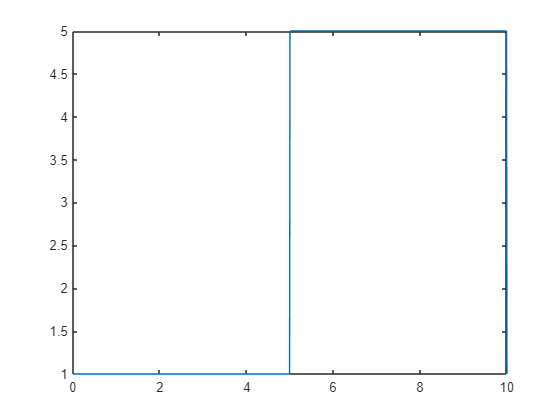

%输入整形法 连续及离散方式实现

%%%%%离散方案
%说明：这也是以离散方式进行给定指令与成形器脉冲直接卷积
clc;clear;

ts=0.01;
Tfin = 10;

t = 0:ts:Tfin;
nu = length(t);

%本身系统传递函数

w=5; zeta = 0.1;

num = [0 0 w^2];
den = [1 2*w*zeta w^2];

s1 = tf(num,den);

%%给定指令
u1 = ones(1,nu);
u1(501:1000) = 5;
plot(t,u1);

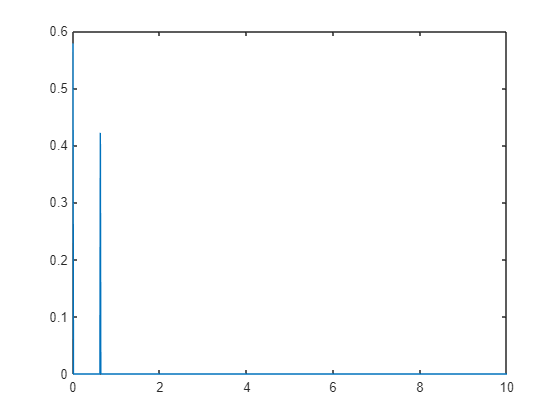


%成形器脉冲指令
%第一个脉冲时间是0 第二个脉冲时间是td
td = pi / (w*sqrt(1-zeta^2));
K = exp((-zeta*pi)/(sqrt(1-zeta^2)));
%第一个幅值A1 第二个A2
A1 = 1/(1+K);
A2 = K/(1+K);
u2 = zeros(1,nu);
u2(1) = A1;
u2(floor(td/ts+1)) = A2;
plot(t,u2);

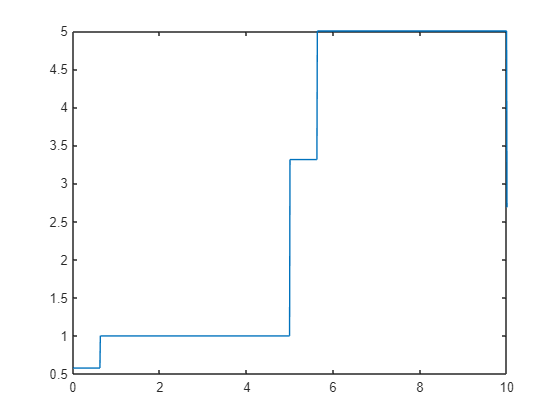


%成形器输出指令起始时间
utbegin = 0 + 0;
utend = Tfin + Tfin;
ut = (utbegin:ts:utend)';
u = conv(u1,u2);
u(nu+1:end) = [];
ut(nu+1:end) = [];
plot(ut,u);

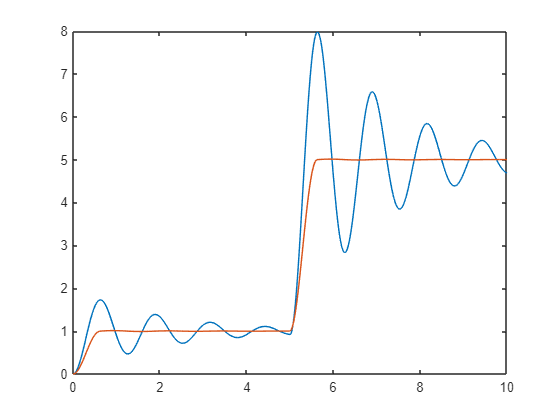


yg1 = lsim(s1,u1,t);
yg2 =lsim(s1,u,ut);
plot(t,yg1,ut,yg2);




% %%%%%%%连续方案
% %说明：下面这段代码完成的是对一个二阶系统加入ZV成形器的结果
% % 均以传递函数形式表示二阶系统 和 ZV成形器
% % clear;clc;close;
% ts = 0.01;
% t = 0:ts:10;
% %本身系统传递函数
% w=5;zeta = 0.1;
% num = [0 0 w^2];
% den = [1 2*w*zeta w^2];
% s1 = tf(num,den);
% %第一个脉冲是0 第二个脉冲是td
% td = pi / (w*sqrt(1-zeta^2));
% K = exp((-zeta*pi)/(sqrt(1-zeta^2)));
% %第一个幅值A1 第二个A2
% A1 = 1/(1+K);
% A2 = K/(1+K);
% %zv shaper 传递函数
% s=tf('s');
% s2 = A1 + A2*exp(-td*s);
% sys = s1 * s2;
% step(s1,t);
% hold on
% step(sys,t);
% legend('整形前','整形后');
% hold off
% % impulse(s1,t);
% % hold on
% % impulse(sys,t);
% % legend('整形前','整形后');
% % hold off



